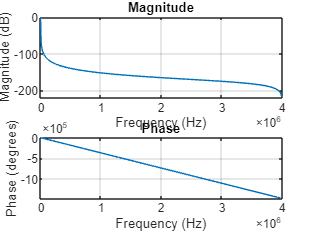

close all; clear all; clc;

% Signal Length
L = 8000000;

% Read Signal with center frequency 66 kHz
[A, Fs] = audioread("C:\Path\To\RBU\RBU.wav", [1,L]);

% Timestamp
t=((0:L-1)/Fs);

% Assign I and Q from file
inphase = A(:,1);
quadrature = A(:,2);
IQData = inphase+1i*quadrature;

% Lowpass FIR filter
N    = 16383;    % Order
fc   = 1200;     % Cutoff Frequency
flag = 'scale';  % Sampling Flag

% Create the window vector for the design algorithm.
win = barthannwin(N+1);

% Calculate the coefficients using the FIR1 function.
b  = fir1(N, fc/(Fs/2), 'low', win, flag);

    
% Visualize magnitude and phase responses
freqz(b,1,[],Fs);

Y = fft(IQData);

subplot(2,1,1);

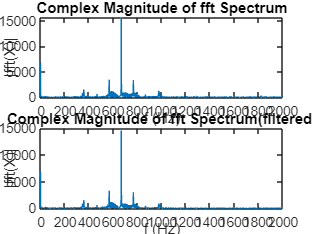

plot(Fs/L*(-L/2:L/2-1),abs(fftshift(Y)))
title("Complex Magnitude of fft Spectrum")
xlabel("f (Hz)")
ylabel("|fft(X)|")
xlim([0, 2000])

% Filter all additional frequencies and noise
IQData = filter(b,1,IQData);
% In case of filtering with IIR filter
IQData = filtfilt(b,1,IQData);

inphase = real(IQData);
quadrature = imag(IQData);

Y = fft(IQData);

subplot(2,1,2);
plot(Fs/L*(-L/2:L/2-1),abs(fftshift(Y)))
title("Complex Magnitude of fft Spectrum(filtered)")
xlabel("f (Hz)")
ylabel("|fft(X)|")
xlim([0, 2000])

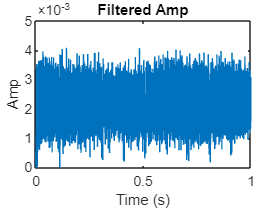

 
%  Freq =[0; (diff(quadrature).*inphase(2:end)-diff(inphase).*quadrature(2:end))./(quadrature(2:end).^2+inphase(2:end).^2)*Fs - 2*pi-Fc];
% Freq = [0;diff(unwrap(angle(IQData)))*Fs-2*pi*Fc];

% Calculate signal amplitude
Amp = sqrt(quadrature.^2+inphase.^2);

% Plot filtered amplitude
figure();   
plot(t,Amp)
title("Filtered Amp")
xlabel("Time (s)")
ylabel("Amp")

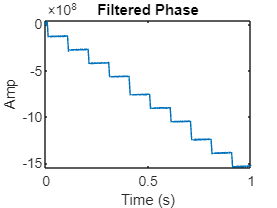


% Calculate signal phase

% Using unwrap function and phase correction (2*pi*deltaF*t)
% Phase = unwrap(angle(IQData))-2*pi*666*t';
% Using FM reciever with following integration. Multiply by Fs is used to
% correct numerical differentiation with finite differences
% For more, use: 
Phase = [0; cumtrapz((diff(quadrature).*inphase(1:end-1)-diff(inphase).*quadrature(1:end-1))./(quadrature(2:end).^2+inphase(2:end).^2)*Fs - 2*pi*666)];

% Plot filtered phase
figure();   
plot(t,Phase)
title("Filtered Phase")
xlabel("Time (s)")
ylabel("Amp")